# The Beauty of Control

This group work will drive you through the amazing world of modern control theory using one of the "hottest systems" in current engineering. It will show you how complex systems, like wind turbines, can be modeled and analysed through powerful analytical and computational tools. The power of feedback will unfold in front of you, and you will get a tasty bite of what you will be able to do as control engineer at the end of the course when you will master these engineering tools.

## Wind Turbine Dynamics

A model for a horizontal axis wind turbine with flexible drive train subject to aerodynamic forces is described in the following.

**Aerodynamics**

The efficiency of a wind turbine is described using a power surface which is taken as a function of the blade's pitch angle $\beta$ and tip-speed ratio $\lambda$ (see a graphical representation in the two figures below)

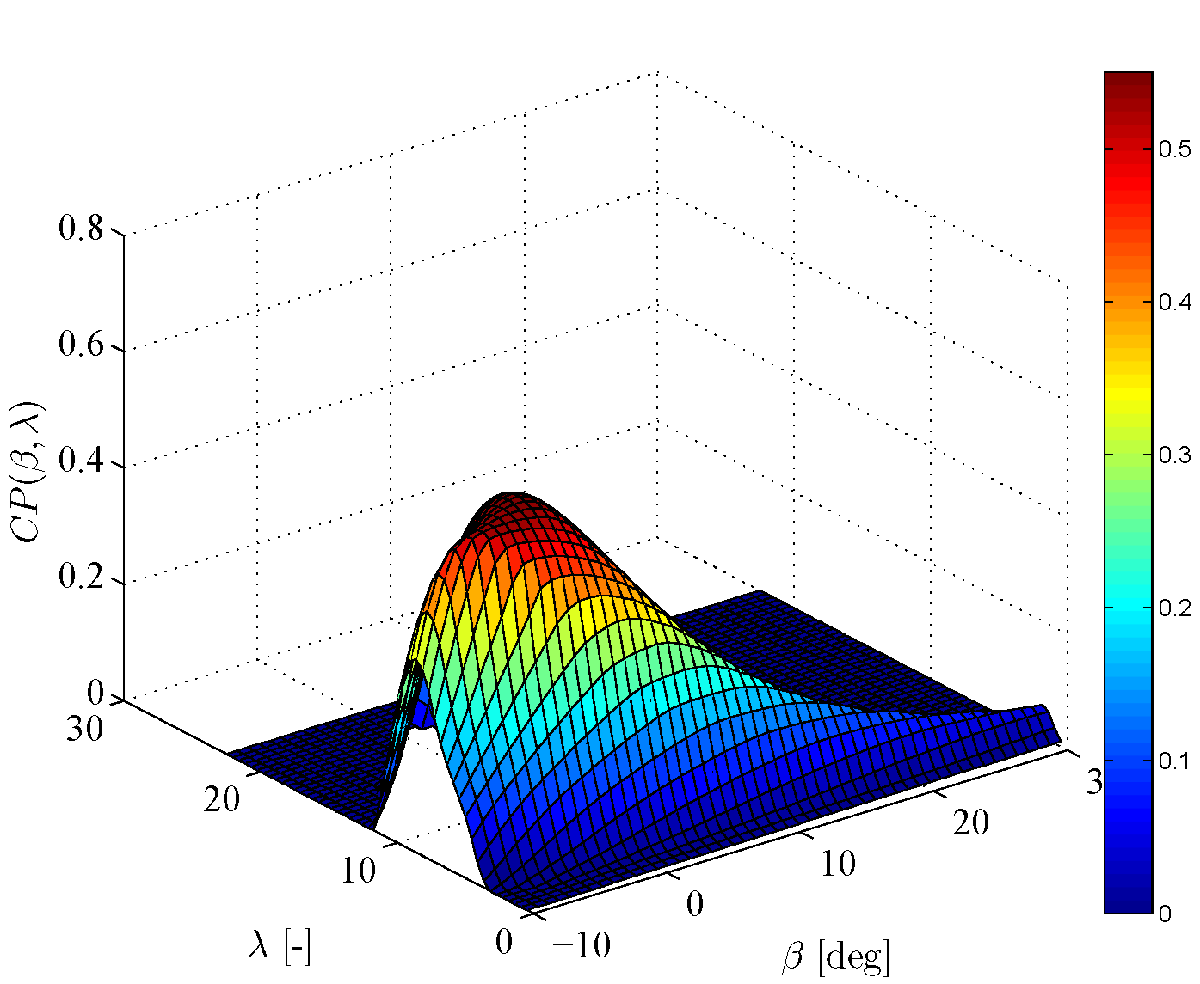                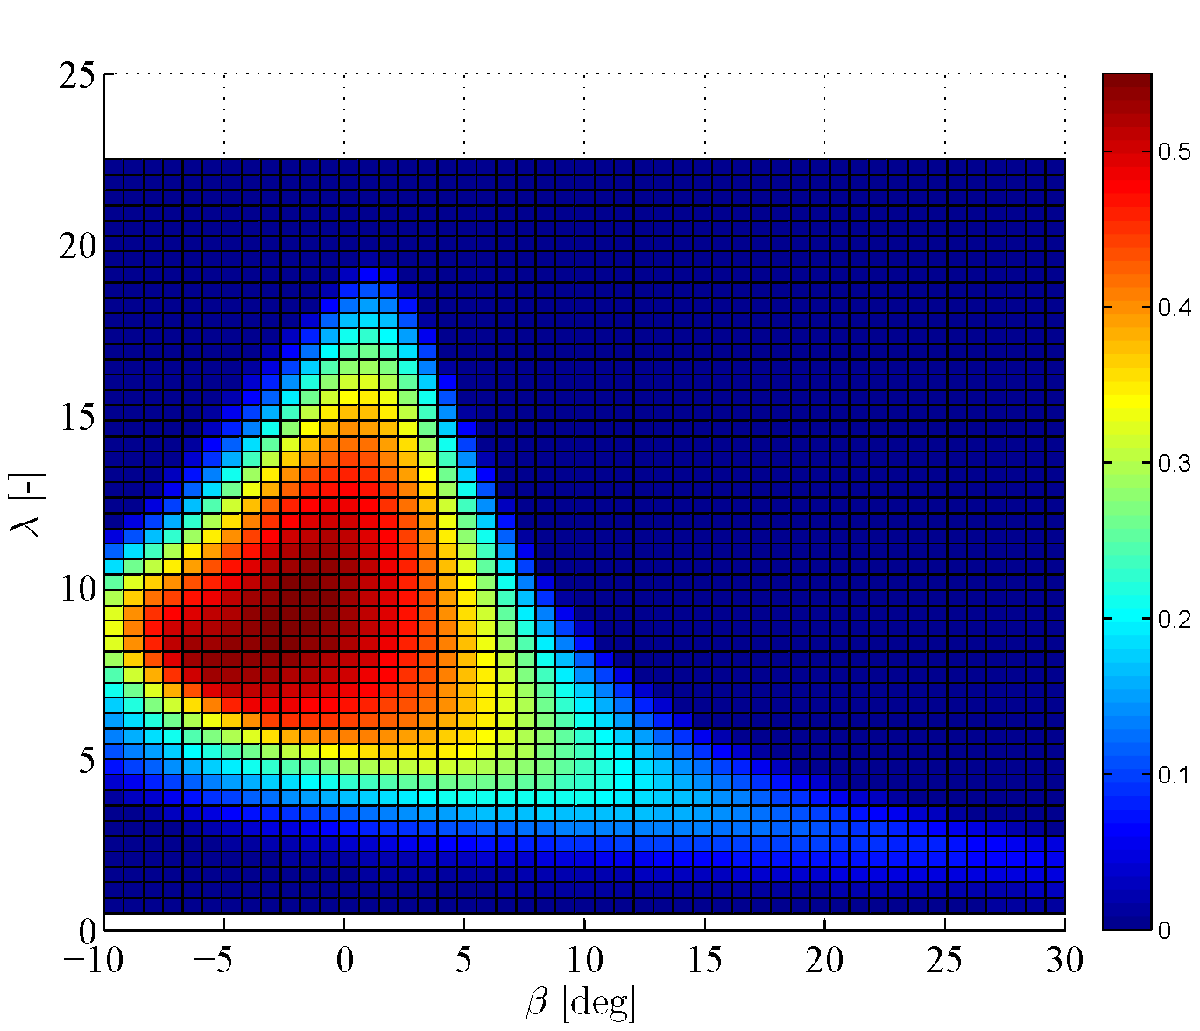

The power coefficient $\mathrm{CP}(\beta,\lambda)$ is the ratio between aerodynamic rotor power $P_a$ and the available wind power $P_w$, and it defines the percentage of power that is possible to capture

(1)                                                    $\mathrm{CP}(\beta,\lambda) = \frac{P_a}{P_w}$                                               

where $\lambda$ is defined as

(2)                                                         $\lambda =  \frac{R \omega_r}{v}$

with $\omega_r$ being the rotor angular velocity, $R$ being the rotor radius, and $v$ is the wind speed. Mathematical closed form descriptions of the power coefficient as a function of the tip-speed ratio and the pitch angle are very difficult and, although some attempts with different degree of success have been done, it is common practice to use the CP surface as generic function of $\lambda$ and $\beta$ for carrying out the analysis, and to use a look-up table for simulation purposes.

The available power from the wind is

(3)                                                    $P_w = \frac{1}{2}\rho A v^3$

where $\rho$ is the air density, and $A = \pi R^2$ is the area swept by the rotor. Inserting (3) into (1) the power captured by the wind turbine can be obtained as

(4)                                                $P_a = \frac{1}{2}\rho A \mathrm{CP}(\beta,\lambda) v^3$

The aerodynamic torque $T_a$ responsible for the motion of the wind turbine rotor can be directly derived from (4) as

(5)                                          $T_a = \frac{P_a}{\omega_r} = \frac{1}{2}\rho A R \mathrm{CP}(\beta,\lambda) \frac{v^2}{\lambda}$

**Drive train dynamics**

The two-mass drive train model consists of two shafts interconnected by a gearbox. The aerodynamic torque $T_a$ drives the low-speed shaft at the rotor speed $\omega_r$, while the gearbox increases the angular speed of the high-speed shaft to $\omega_g$ while lowering the torque. Thereby the drive train converts wind energy to mechanical energy and, through the generator, to electrical energy.

The inertia of the rotor and generator is respectively lumped into $J_r$ and $J_g$; $T_{ls}$, $T_{hs}$, and $T_g$ denote the low-speed shaft torque, the high-speed shaft torque, and the generator torque respectively. The stiffness of the shafts are modeled through damping and torsional coefficients $B_{d}$ and $K_{d}$. 

The inertia of the low-speed shaft includes the inertia of the rotor, while the friction component includes bearing frictions. The dynamics of the low-speed shaft is given by

(6)                                                    $J_r\dot{\omega}_r = T_a - T_\mathrm{ls}$

The high-speed shaft has similar dynamics, which includes the inertia of the gearbox and generator, and the friction from bearing and gears

(7)                                                    $J_g\dot{\omega}_g = T_\mathrm{hs} - T_g$

The drive train torsion is modeled as the sum of a torsional spring force and a frictional force

(8)                                                    $T_\mathrm{ls} = K_{d}\theta + B_{d}\dot{\theta}$

where $\theta = \theta_r - \theta_g/N_g$ is the torsional angle, given as the difference between the rotor angular position $\theta_r$ and the generator angular position $\theta_g$ scaled by the drive train gear ratio $N_g$. The low-speed and high-speed shaft are interconnected by the gearbox such that

(9)                                                        $N_g = \frac{T_\mathrm{ls}}{T_\mathrm{hs}}$

## Problems

**P1    **Derive the analytical model of the wind turbine. *Hint: the dynamical model of the wind turbine is described by 3 differential equations. The first equation describes how the angular velocity of the rotor changes over time.*

**P2   ** Open the Simulink diagram *OpenLoopWindTurbineModel_2014.slx*. Explore the block Wind Turbine and identify in the Simulink diagram the model equations previously derived. If your analytical model is well derived then the you should be able to match each element of your mathematical model with an element in the Simulink diagram.

% Open the Simulink diagram OpenLoopWindTurbineModel_2014.slx
open('OpenLoopWindTurbineModel_2014.slx')

**P3    **Run the code section below. Display the numerical values of the input and internal variables defining the wind turbine operating point. Then go to the Simulink model and run a simulation of the open-loop system. Open the two scopes (System Input Variables and System Output Variables) and compare these values with those previously displayed.

% First we load the numerical values of the parameters used by 
% the model
load('OpenLoopWindTurbine_Parameters.mat')
% Then we load the numerical values of the wind turbine variables 
% which define the operating point
load('OpenLoopWindTurbine_OperatingPoint.mat');
% Check the numerical values of the wind turbine input variables 
% (v_OP, beta_OP, Tg_OP) and internal variables (x0 = [wr_OP wg_OP th_OP]')
disp('Operating point:')

Operating point:


disp('* System variables')

* System variables


disp(strcat('Rotor angular velocity (omega_r) [rad/s]:',num2str(w_OP)))

Rotor angular velocity (omega_r) [rad/s]:1.2671


disp(strcat('Generator angular velocity (omega_g) [rad/s]:',num2str(wg_OP)))

Generator angular velocity (omega_g) [rad/s]:122.9096


disp(strcat('Torsional angle (theta) [deg]:',num2str(th_OP*rad2deg)))

Torsional angle (theta) [deg]:0.26058


disp(strcat('Electrical power (Pe) [MW]:',num2str(Tg_OP*wg_OP/1e6)))

Electrical power (Pe) [MW]:5


disp('* System inputs')

* System inputs


disp(strcat('Blade pitch angle (beta) [deg]:',num2str(beta_OP*rad2deg)))

Blade pitch angle (beta) [deg]:17.5836


disp(strcat('Generator torque (Tg) [KNm]:',num2str(Tg_OP/1e3)))

Generator torque (Tg) [KNm]:40.6803


disp(strcat('Wind speed (v) [m/s]:',num2str(v_OP)))

Wind speed (v) [m/s]:20


% Run a simulation with the Simulink diagram OpenLoopWindTurbineModel_2014.slx


**P4    **Given the behavior over time of the system variables that you can see on the scopes, would you say that the system is in a stationary condition? Try to change e.g. the wind speed to $v_{OP} = 22\;\mathrm{m}/\mathrm{s}$ and see what happens. After this simulation remember to set $v_{OP} = 20\;\mathrm{m}/\mathrm{s}$ again

% Run a new simulation with v_OP = 22 m/s and evaluate differences with
% the previous simulation
 
v_OP = 20;
% Before proceeding further in the exercise set v_OP = 20 m/s


**P5    **Real physical systems are always controlled through different kind of actuators (hydraulic, electric, pneumatic, electro-mechanical, etc.). The actuators are responsible of delivering the control action requested by the control system to the physical system, such that the physical system behaves as desired. Let's see how many actuators we have in our model by opening the Simulink diagram *OpenLoopWindTurbineModel_withActuators2014.slx*. How many actuators are present in the model? Do you know what function do they carry out in the system?

% Open the Simulink diagram OpenLoopWindTurbineModel_withActuators2014.slx
open('OpenLoopWindTurbineModel_withActuators2014.slx')

**P6    **Neglecting the presence of the saturation blocks, write down the transfer functions representing the actuators. Which are the order of the systems representing the actuators? Plot a Bode diagram of the two transfer functions and analyse the system properties in the frequency domain (DC gain and bandwidth)

% Plot the Bode diagrams of the actuators transfer functions

% Compute the DC gain and the bandwidth of the actuators


No doubt that the model of the wind turbine we have seen so far is rather complex, especially due to the intricate description of the aerodynamic torque $T_a$, which is actually defined only numerically through the look-up table providing the power coefficient $\mathrm{CP}(\beta,\lambda)$.

In the course we will see that in order to analyse the system dynamics and to design advanced controllers we do not need to deal with the complexity of the nonlinear dynamical models. The powerful tool of *Linearization* will be used to obtain an approximation of the complex nonlinear system in a neighborhood of the operating point. Is it really true that a simple linear model can well describe the complex nonlinear dynamics of the wind turbine? Let's see ...

**P7    **Open the Simulink diagram* OpenLoopWindTurbineModel_LinearVsNonlinear2014.slx*. Explore the diagram and discuss what you see inside the two Wind Turbine blocks. Try to write down the equations describing the Wind Turbine (linearized model).

% Open the Simulink diagram OpenLoopWindTurbineModel_LinearVsNonlinear2014.slx
open('OpenLoopWindTurbineModel_LinearVsNonlinear2014.slx')

P8    Run the section code below. Display the system matrices $A_{ol}$, $B_{ol}$, $B_{v}$, $C_{ol}$, and $D_{ol}$ and check their dimensions. Considering their dimensions and the diagram you explored in the previous problem, to which variables do you think they relate?

% First load the linear model of the wind turbine obtained by linearizing
% the nonlinear model around the operating point 
load('OpenLoopWindTurbine_LinearModel.mat');
% Display the matrices Aol, Bol, Bv, Col and Dol of the linear open loop system

% Compute the size of each matrix


**P9**    Run a simulation using the Simulink diagram *OpenLoopWindTurbineModel_LinearVsNonlinear2014.slx.* Keep the switches in the "up" position (**NOT** connected to the "step" blocks). Open the scope System Output Variables and look at the signals displayed. Is the Wind Turbine (linearized model) block capable of representing the behavior of the Wind Turbine (nonlinear model)? Generate a Matlab figure where the signals of the Wind Turbine (nonlinear model) and these of the Wind Turbine (linearized model) are compared.

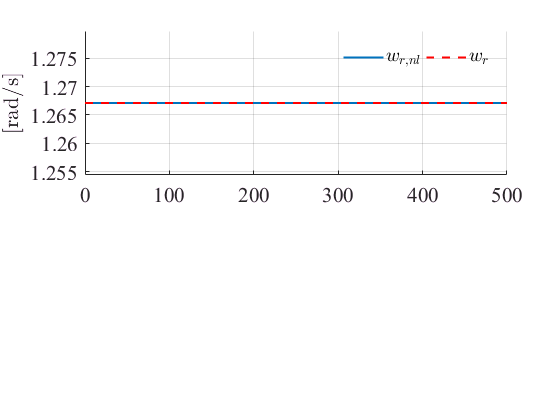

% Define an input variables vector u0
u0 = [beta_OP Tg_OP]'; % [blade pitch angle, generator torque]
% Define an output variables vector y0
y0 = [x0(1) 5e6]'; % [rotor angular velocity, electrical power]

% Run the simulation of the Simulink diagram OpenLoopWindTurbineModel_LinearVsNonlinear2014.slx


% Extract signals from simulation output
time = omega_r.time;
wr_nl = omega_r.signals.values(:,1); % rotor angular velocity nonlinear model
wr = omega_r.signals.values(:,2); % rotor angular velocity linear model
% wg_nl = 
% wg = 
% th_nl = 
% th = 
% Pe_nl = 
% Pe = 

% Compare outputs of nonlinear and linearized models
figure
h1 = subplot(2,1,1); 
set(h1,'FontName','times','FontSize',16);
hold on, grid on
plot(time,wr_nl,time,wr,'--r','LineWidth',1.5)
ylabel('[rad/s]','FontName','times','FontSize',16,'Interpreter','latex')
l1 = legend('$w_{r,nl}$','$w_r$','Orientation','horizontal');
set(l1,'FontName','times','FontSize',14,'Interpreter','latex','Box','off')
ylim([0.99 1.01]*x0(1))

% h2 = subplot(2,1,2);


**P10**    Step signals are used for describing abrupt changes in some system signals of importance (e.g. inputs, disturbances, references). In order to see the effects of abrupt changes of the wind speed and the blade pitch angle in the system, carry out a series of simulations each time setting **ONE** of the switches to the "down" position. Use the following values for the step signals:

- wind speed: $$\pm 1 \; \mathrm{m}/\mathrm{s}$$, $$\pm 2.5 \; \mathrm{m}/\mathrm{s}$$

- blade pitch angle: $$\pm 1 \; \mathrm{deg}$$, $$\pm 2.5 \; \mathrm{deg}$$

For each step change plot the system outputs for the linear and nonlinear model and discuss on the response of the systems to these changes. When is the linearized model a good approximation of the nonlinear model?

% Step up & down in the wind speed (small step +/- 1 m/s and large step +/- 2.5 m/s from the wind operating point)
StepTime_wind = 100;
StepFinalValue_wind = v_OP + 1;
% Run a simulation on the Simulink diagram OpenLoopWindTurbineModel_LinearVsNonlinear2014.slx

% Plot results

% Repeat for the other cases
% StepFinalValue_wind = v_OP - 1;

% Step up & down in the pitch angle (small step +/- 1 deg and large step +/- 2.5 deg from the pitch angle operating point)
StepTime_wind = TIME_SIM;
StepFinalValue_wind = 20;
StepTime_pitch = 100;
StepFinalValue_pitch = beta_OP + 1*deg2rad; % the pitch angle is in radians
% Run a simulation on the Simulink diagram OpenLoopWindTurbineModel_LinearVsNonlinear2014.slx

% Plot results

% Repeat for the other cases
% StepFinalValue_pitch = beta_OP - 1*deg2rad;


Now that we have seen a bit about modeling of dynamical systems and that we got some insight on how good/bad a linear model can be, let us move to the even more interesting part ... Control, yeah!

In the course we will go through several control architecture offering us differing level of flexibility in reaching control requirements. That one you will see now in action is one of the "sexiest" ... so let's give it a look.

For a wind turbine operating in the full load region, the control objectives are to regulate the rotor angular velocity $$\omega_r$$ and the generated electrical power $$P_e$$ to their respective nominal values with zero steady state errors despite wind variations. Moreover the controller should avoid (as much as possible) that the actuators (blade pitch actuator and the generator) works in/close to saturation.

**P11**    Open the model *ClosedLoopWindTurbineModel_FullStateOptimalController2014.slx*. How many variables is the controller receiving as inputs? How many control signals does it deliver? To your knowledge, would it be possible to design a PID regulator that exploits all the available signals?

% Open the Simulink diagram ClosedLoopWindTurbineModel_FullStateOptimalController2014.slx
open('ClosedLoopWindTurbineModel_FullStateOptimalController2014.slx')

**P12**    In order to better understand what exactly the controller does to the system, carry out a series of simulations operating first at the $$v_{op}$$ (set the manual switch to the "up" position) and then applying step changes (manual switch to the "down" position). Pick the values for the step signal appropriately, so that both small and large changes in the wind speed are simulated. Why can we change only the wind speed in the simulation (and not the blade pitch angle)? Discuss the action of the controller on the system in all cases.

% First let's extend the vector of initial conditions
x0 = [x0; beta_OP; Tg_OP]; % [rotor angular velocity, generator angular velocity, torsional angle, pitch angle, generator torque]
% Then load the parameter defining the control system
load('CloseLoopWindTurbine_OptimalControllerParameters.mat')
% Run simulations on the Simulink diagram ClosedLoopWindTurbineModel_FullStateOptimalController2014.slx
% applying changes in wind speed
StepTime_wind = 100;
% Try to change the final value of th wind speed and see how the controller reacts
StepFinalValue_wind = v_OP + 1; 

The last stop of this journey coincides with one of the major (if not the major) achievement in modern linear control theory, i.e. the reconstruction of missing system information based on measured signals.

In P11 we have seen that the very advanced controller designed for the wind turbine exploits all the signals we actually used to describe the turbine dynamics. Is this a realistic scenario? The answer is obviously no. In everyday control applications there will always be a limited amount of sensors at disposal of the control engineer. This is due to budget limitations or to the fact that the variables we would like to know, are actually not measurable.

At the end of the '50s Rudolph Kalman, a giant of modern control theory, developed a system that is capable of reconstructing in an optimal manner the behavior of the unmeasured system variables based on the measurements of some other system variables. This system is known as the **Kalman Filter** and it has been at the core of many engineering applications way beyond control theory for the last 60 years.

**P13**    Open the model *ClosedLoopWindTurbineModel_OutputFeedbackOptimalController2014.slx*. The variables available for measurement are the rotor angular velocity $$\omega_r$$ and the electrical power $$P_e$$. The other internal signals are unknown and not measurable. Look at the block diagram and highlight differences with respect to the block diagram of Problem 11. Which are the inputs of the Linear Optimal State Estimator? What kind of outputs it produces?

% Open the Simulink diagram ClosedLoopWindTurbineModel_OutputFeedbackOptimalController2014.slx
open('ClosedLoopWindTurbineModel_OutputFeedbackOptimalController2014.slx')

**P14**    Carry out a series of simulations operating first at the $$v_{op}$$ (set the manual switch to the "up" position inside the Wind Speed Generator) and then applying step changes (manual switch to the "down" position). Pick the values for the step signal appropriately, so that both small and large changes in the wind speed are simulated. Is the controller capable of fulfilling the control requirements even tough only two variables are measured? Is the Linear Optimal State Estimator capable of reconstructing the wind speed signal?

% Load the parameters of the output feedback optimal controller
load('ClosedLoopWindTurbine_StochasticOptimalControllerParameters.mat')
% Run simulations on the Simulink diagram ClosedLoopWindTurbineModel_OutputFeedbackOptimalController2014.slx
% applying changes in wind speed
StepTime_wind = 100;
% Try to change the final value of th wind speed and see how the controller reacts
StepFinalValue_wind = v_OP + 1;